man = imread('man.jpg');
girl = imread('girl.jpeg');
%imshow(man);

提取面部

Detector = vision.CascadeObjectDetector('FrontalFaceCART');     %face detector
bboxes = step(Detector,man);
man_face_idx = [bboxes(2),bboxes(1);bboxes(2)+bboxes(4),bboxes(1)+bboxes(3)];   %[面部的左上角坐标;面部的右下角坐标]
man_face = man(man_face_idx(1,1):man_face_idx(2,1) , man_face_idx(1,2):man_face_idx(2,2),:);


bboxes = step(Detector,girl);
girl_face_idx = [bboxes(2),bboxes(1);bboxes(2)+bboxes(4),bboxes(1)+bboxes(3)];%[面部的左上角坐标;面部的右下角坐标]
girl_face = girl(girl_face_idx(1,1):girl_face_idx(2,1) , girl_face_idx(1,2):girl_face_idx(2,2),:);


%imshow(man_face)
%imshow(girl_face)

feature = detectSURFFeatures(rgb2gray(man_face));  %转化为灰度图后提取特征
imshow(man_face);
hold on;
strongest = feature.selectStrongest(4);    %从右到左从上到下
strongest.Location
plot(strongest);
man_feature = [feature]

girl_face_feature = detectSURFFeatures(rgb2gray(girl_face)); %转化为灰度图后提取特征
imshow(girl_face);
hold on;
strongest = girl_face_feature.selectStrongest(2);    %从左到右
strongest.Location
plot(strongest);

## 手动选择特征点

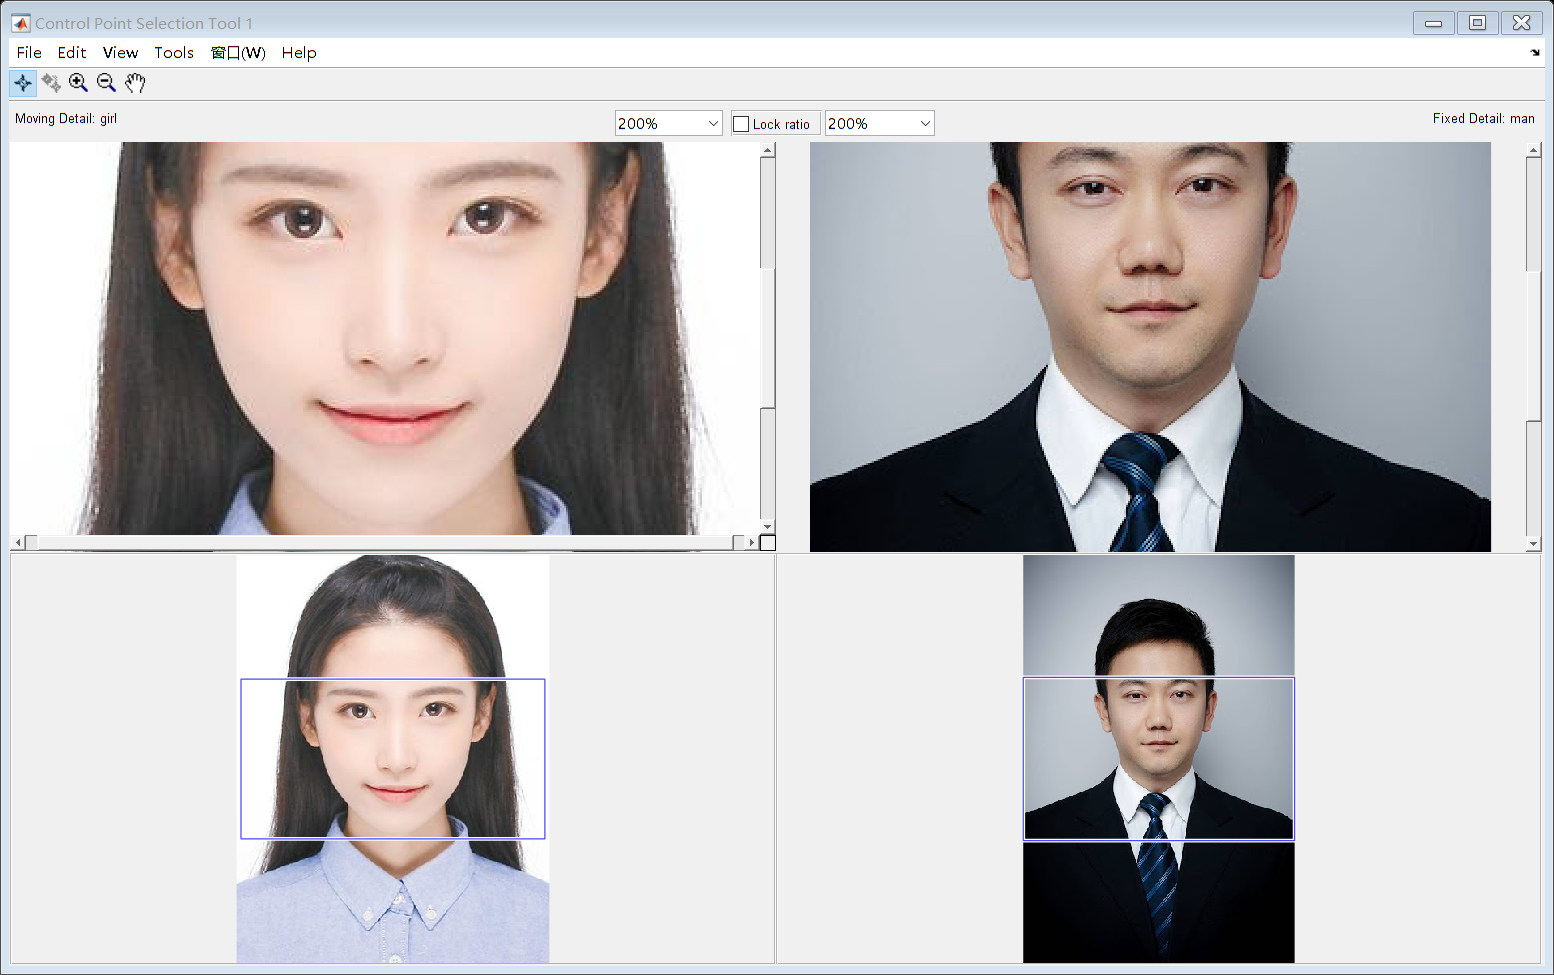

man = imread('man.jpg');
girl = imread('girl.jpeg');
cpselect(girl,man)  %打开交互程序，打特征点

save('girl_features.mat','girl_features')
save('man_features.mat','man_features')

girl_features

girl_features =   152.7500  193.2500
  243.2500  189.7500
  196.7500  261.2500
  198.0291  293.2747
  195.3225  341.8214
  104.0000  235.0000
  290.0000  233.0000
  196.0000   81.0000


man_features

man_features =   142.3103  176.9291
  197.2375  175.4579
  170.2644  212.9751
  171.3487  238.2608
  170.4800  275.2190
  110.2215  221.4933
  226.1946  220.6342
  169.0674  112.6272


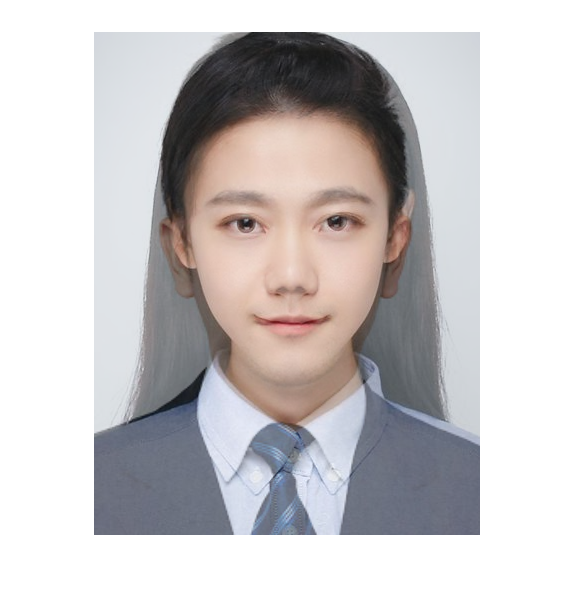

tform = fitgeotrans(man_features,girl_features,'NonreflectiveSimilarity');
man_registered = imwarp(man,tform,'OutputView',imref2d(size(girl)));
figure
imshowpair(girl,man_registered,'blend')